## Noah SoRoSim Live Script

close all;
clear;
clc;
set(0, 'DefaultFigureVisible', 'on');

load("my_robot.mat")
s=0.1;
S1.VLinks.r = {@(X1)1.125e-3};
S1.Update()

ans =   SorosimLinkage with properties:

                      N: 1
                   ndof: 14
                   nsig: 103
                     nj: 102
                 VLinks: [1×1 SorosimLink]
              LinkIndex: 1
                 CVRods: {[1×2 SorosimRod]}
                  iLpre: 0
                  g_ini: [4×4 double]
                Z_order: 4
               OneBasis: 0
                   nCLj: 0
                   iCLA: []
                   iCLB: []
               VRodsCLj: []
                  gACLj: []
                  gBCLj: []
           CLprecompute: [1×1 struct]
                   T_BS: []
                Gravity: 0
                      G: [6×1 double]
                     np: 1
            LocalWrench: 1
                 Fp_loc: {[1 1 1]}
                 Fp_vec: {[@(t)[0,0,0,0,1,0]']}
                 Fp_sig: 103
                    CEF: 0
             UnderWater: 0
              Rho_wat

Solving Static Equilibrium

                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          1         1.00042e+12                           1e+12              1
     1          2         1.45885e+09              1         4.36e+13              1
     2          3            0.574469      0.0303149         7.58e+05            2.5
     3          4         4.43855e-19    7.58431e-07         0.000666            2.5
     4          5         2.49793e-26    7.62704e-16         4.43e-05            2.5

Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance

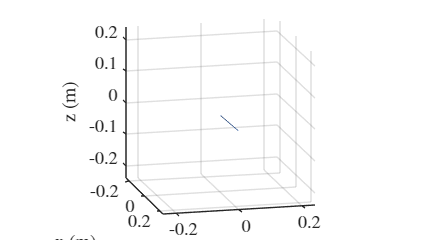

q =          0
         0
         0
         0
         0
         0
    0.0147
   -0.0998
    0.0208
   -0.2218


u =          0
         0
   -0.0203
    0.0231
   -0.9997
         0
         0



lambda =

  0×1 empty double column vector



[~, quadpoints] = S1.CVRods{1}.Xs;
[~, idx] = min(abs(quadpoints - s)); % round s to nearest quadpoint
s_rounded = quadpoints(idx);
S1.Fp_loc = {[1 1 s_rounded]};
S1.Fp_sig = PointWrenchPoints(S1);
S1.plotq0
%S1.CEFP=1 % custom force
x0 = zeros(14,1);
action = [0;0;0;0;0;0];
[q,u,lambda] = S1.statics(x0, action)


Mz = u(3);
Fx = u(4);
Fy = u(5);
